# Custom Training Loop

## Preprocessing

inhale_data = readmatrix("res\inhale_data_v5.csv");
exhale_data = readmatrix("res\exhale_data_v5.csv");
inhale_outcome = readtable("res\inhale_outcome_v5.csv");

exhale_outcome = readtable("res\exhale_outcome_v5.csv");

inhale_verbose = readtable("res\inhale_verbose_v5.csv");
exhale_verbose = readtable("res\exhale_verbose_v5.csv");
inhale_outcome = table2array(inhale_outcome);
exhale_outcome = table2array(exhale_outcome);
inhale_verbose = table2array(inhale_verbose);
exhale_verbose = table2array(exhale_verbose);
% coeff = pca(train_data(:,1:end-1), "NumComponents", 20);
% train_data = [coeff' train_data(:,end)];

% valid_idx = (exhale_verbose(:,3)<=18) & ((exhale_outcome(:,1)==1) | (exhale_outcome(:,1)==2)) & (~isnan(exhale_outcome(:,6)));
valid_idx = ((exhale_outcome(:,1)==1) | (exhale_outcome(:,1)==2)) & (~isnan(exhale_outcome(:,6)));
raw = exhale_data(valid_idx,:);
% manual_removal = [15 18 21 22 25 26 70 74 77 90 97 98 106 107 108 123 138 140 142 144 145 ...
%     170 180 186 192 205 206 209 212 229 230 232 233 247 259 273 279 280 281 293 295 ...
%     316 337 368 372 379 381];
% raw(manual_removal,:) = [];
data = cell(size(raw,1),1);
mask = cell(size(raw,1),1);
% if ~exist('heatmap', 'dir')
%     mkdir('heatmap');
% end
for i = 1:size(raw,1)
    tmp = reshape(raw(i,:),[],25);
    [data{i}, mask{i}] = generate_heatmap_v2(tmp(31:126,:));
    data{i} = data{i}.*mask{i};
%     imwrite(flipud(data{i}),['heatmap\' num2str(i) '.png']);
end


% Centering/Normalization
% data = (data-mean(data,2))./std(data,[],2);

label = categorical(exhale_outcome(valid_idx,1));
% label(manual_removal,:) = [];
spiro = exhale_outcome(valid_idx,5:6);
% spiro(manual_removal,:) = [];
verbose = exhale_verbose(valid_idx,:);
% verbose(manual_removal,:) = [];
classes = categories(label);

% c = cvpartition(label,"KFold",5);
u = unique([verbose(:,1) double(label)],'rows');
c = cvpartition(u(:,2),"KFold",5);
% subject = unique(verbose(:,1));
% c = cvpartition(subject,"KFold",5);


## Config Hyperparameters

numEpochs = 50;
miniBatchSize = 32;

initialLearnRate = 0.0001;
decay = 0.01;
gradientDecayFactor = 0.9;
squaredGradientDecayFactor = 0.999;

## MTK model

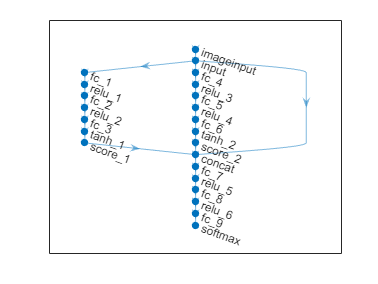

numFeatures = size(data, 2);

load("encoder_heatmap_v5.mat");
for i = 1:length(encoder.Learnables.Value)
    encoder.Learnables.Value{i} = gpuArray(encoder.Learnables.Value{i});
end

layers = [ ...
    imageInputLayer([12 12 32],Normalization="none")
    flattenLayer("Name","input")
    fullyConnectedLayer(50)
    reluLayer
    fullyConnectedLayer(50)
    reluLayer
    fullyConnectedLayer(1)
    tanhLayer('Name','tanh_1')
    functionLayer(@(X) 100*X+100,Name="score_1")];
lgraph = layerGraph(layers);

layers = [ ...
    fullyConnectedLayer(50)
    reluLayer
    fullyConnectedLayer(50)
    reluLayer
    fullyConnectedLayer(1)
    tanhLayer('Name','tanh_2')
    functionLayer(@(X) 100*X+100,Name="score_2")];
lgraph = addLayers(lgraph, layers);
lgraph = connectLayers(lgraph,"input","fc_4");

layers = [ ...
    concatenationLayer(1,3)
    fullyConnectedLayer(50)
    reluLayer
    fullyConnectedLayer(50)
    reluLayer
    fullyConnectedLayer(2)
    softmaxLayer];
lgraph = addLayers(lgraph, layers);
lgraph = connectLayers(lgraph,"input","concat/in1");
lgraph = connectLayers(lgraph,"score_1","concat/in2");
lgraph = connectLayers(lgraph,"score_2","concat/in3");
plot(lgraph);

## MTK Training

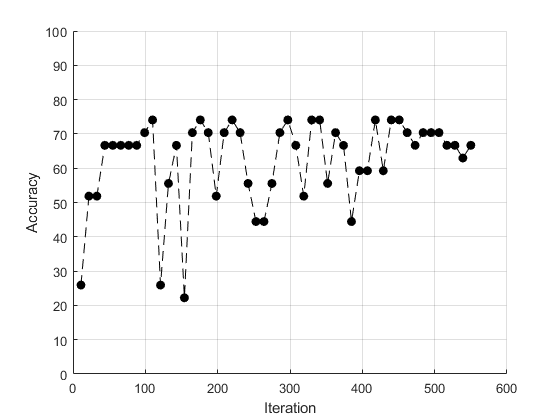

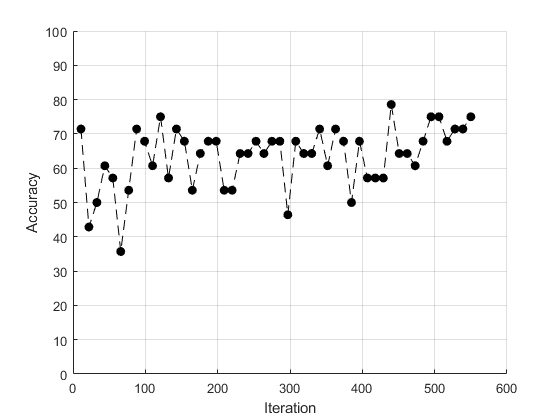

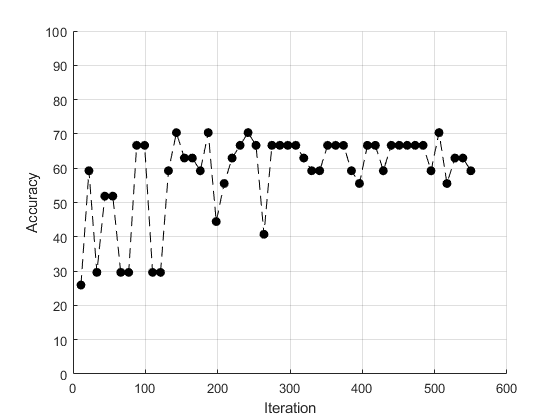

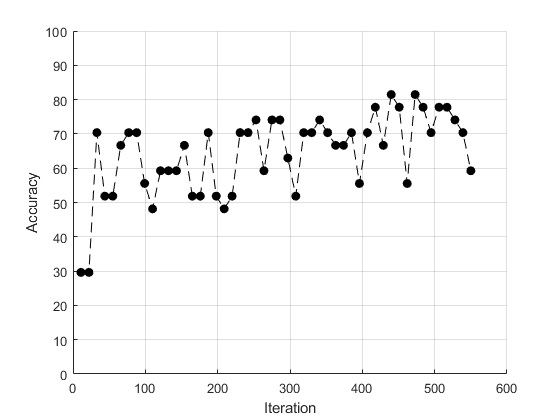

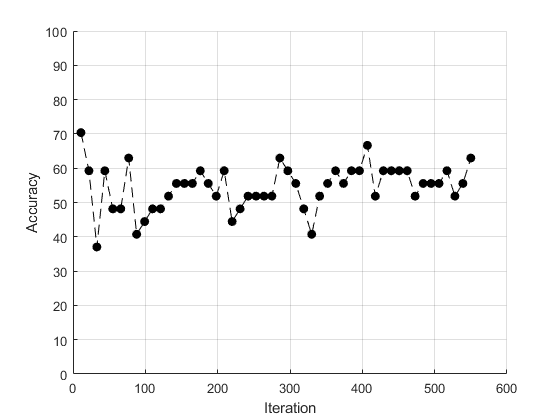

results = {};
results_verbose = {};
for cvidx = 1:5
    net = dlnetwork(lgraph);

    % Initialize Figure
    lossFig = figure;
    C = colororder;
    lineLossTrain = animatedline(Color=C(2,:));
    lineLossValidation = animatedline( ...
        LineStyle="--", ...
        Marker="o", ...
        MarkerFaceColor="black");
    ylim([0 inf]);
    xlabel("Iteration");
    ylabel("Loss");
    grid on;
    
    accFig = figure;
    lineAccTrain = animatedline(Color=C(1,:));
    lineAccValidation = animatedline( ...
        LineStyle="--", ...
        Marker="o", ...
        MarkerFaceColor="black");
    ylim([0 100]);
    xlabel("Iteration");
    ylabel("Accuracy");
    grid on;

    % Cross-validation Partioning (Subject-level leave-one-out)
%     trainidx = training(c,cvidx);
%     testidx = test(c,cvidx);
    trainidx = ismember(verbose(:,1), u(c.training(cvidx),1));
    testidx = ismember(verbose(:,1), u(c.test(cvidx),1));
%     [trainidx,testidx] = splitDataset(label,verbose(:,1),0.2);
%     trainidx = logical(sum(verbose(:,1)==subject(training(c,cvidx))',2));
%     testidx = logical(sum(verbose(:,1)==subject(test(c,cvidx))',2));


    % Prepare minibatch
    tbl = table;
    tbl.data = data(trainidx);
    tbl.label = label(trainidx,:);
    tbl.spiro = spiro(trainidx,:);
    tbl.verbose = verbose(trainidx,:);
    ds = arrayDatastore(tbl,"OutputType","same");
    mbq = minibatchqueue(ds, ...
        'MiniBatchSize', miniBatchSize, ...
        'MiniBatchFcn', @preprocessMiniBatch, ...
        'MiniBatchFormat', {'SSCB','','',''});

    tbl = table;
    tbl.data = data(testidx);
    tbl.label = label(testidx,:);
    tbl.spiro = spiro(testidx,:);
    tbl.verbose = verbose(testidx,:);
    ds = arrayDatastore(tbl,"OutputType","same");
    mbqValidation = minibatchqueue(ds, ...
        'MiniBatchSize', length(tbl.label), ...
        'MiniBatchFcn', @preprocessMiniBatch, ...
        'MiniBatchFormat', {'SSCB','','',''});
    [XVali,TVali,SVali,VVali] = next(mbqValidation);
    
    trailingAvg = [];
    trailingAvgSq = [];
    
    best_acc = 0;
    best_loss = 1e8;
    
    iteration = 0;
    start = tic;
    
    % Loop over epochs.
    for epoch = 1:numEpochs
    
        % Shuffle data.
        shuffle(mbq);
        
        % Loop over mini-batches.
        while hasdata(mbq)
            iteration = iteration + 1;
            
            % Read mini-batch of data.
            [X,T,S] = next(mbq);
            
            % Evaluate the model gradients, state, and loss using dlfeval and the
            % modelLoss function and update the network state.
            [loss,gradients,state] = dlfeval(@modelLoss,encoder,net,X,T,S(1,:),S(2,:));
            net.State = state;
            % Determine learning rate for time-based decay learning rate schedule.
%             learnRate = initialLearnRate/(1 + decay*iteration);

            % Update the network parameters using the Adam optimizer.
            [net,trailingAvg,trailingAvgSq] = adamupdate(net,gradients, ...
                trailingAvg,trailingAvgSq,iteration);
            
            % Display the training progress.
            figure(lossFig);
            D = duration(0,0,toc(start),Format="hh:mm:ss");
            loss = double(loss);
            addpoints(lineLossTrain,iteration,loss);
            title("Epoch: " + epoch + ", Elapsed: " + string(D));
%             drawnow
            
%             figure(accFig);
%             D = duration(0,0,toc(start),Format="hh:mm:ss");
%             acc = double(acc)*100;
%             addpoints(lineAccTrain,iteration,acc);
%             title("Epoch: " + epoch + ", Elapsed: " + string(D));
%             drawnow
        end
        
        % Validation
        F = predict(encoder,XVali);
        [Y0,Y1,Y2] = predict(net,F,Outputs=["softmax" "score_1" "score_2"]);
%         loss_0 = crossentropy(Y0,TVali,'WeightsFormat','UC');
        loss_0 = crossentropy(Y0,TVali,[2 0.67],'WeightsFormat','UC');
        loss_1 = 100*mean(abs((Y1-SVali(1,:))./SVali(1,:)));
        loss_2 = 100*mean(abs((Y2-SVali(2,:))./SVali(2,:)));
        lossValidation = loss_0 + loss_1 + loss_2;
        
        accValidation = subjectAcc(Y0,TVali,VVali(1,:));
%         Y0 = onehotdecode(Y0,classes,1)';
%         T = onehotdecode(TVali,classes,1)';
%         accValidation = sum(Y0==T)/length(Y0);

        if accValidation > best_acc
            best_acc = accValidation;
            best_net = net;
        end

%         if loss_0 + loss_1 + loss_2 < best_loss
%             best_loss = loss_0 + loss_1 + loss_2
%             best_net = net;
%         end

        % Update plot
        figure(lossFig);
        lossValidation = double(lossValidation);
        addpoints(lineLossValidation,iteration,lossValidation);
%         drawnow

        figure(accFig);
        accValidation = double(accValidation)*100;
        addpoints(lineAccValidation,iteration,accValidation);
%         drawnow
    end

    % Validation of best case
    F = predict(encoder,XVali);
    [Y0,Y1,Y2] = predict(best_net,F,Outputs=["softmax" "score_1" "score_2"]);
    
    results{cvidx} = best_acc;
    results_verbose{cvidx} = [Y0;Y1;Y2;TVali;SVali;VVali];
    
    figure(lossFig)
    drawnow
    set(lossFig, 'Visible', 'on');
    saveas(lossFig,"fig\"+ num2str(cvidx) +"_loss.fig");
    figure(accFig)
    drawnow
    set(accFig, 'Visible', 'on');
    saveas(accFig,"fig\"+ num2str(cvidx) +"_acc.fig");
    close("all");
end

results

results = 1×5 cell array
    {[0.7407]}    {[0.7857]}    {[0.7037]}    {[0.8148]}    {[0.7037]}


## Model Loss Function

function [loss,gradients,state] = modelLoss(encoder,net,X,T,S1,S2)

% Forward data through network.
F = predict(encoder,X);
[Y0,Y1,Y2,state] = forward(net,F,Outputs=["softmax" "score_1" "score_2"]);

% Calculate cross-entropy loss.
% loss_0 = crossentropy(Y0,T,'WeightsFormat','UC');
loss_0 = crossentropy(Y0,T,[2 0.67],'WeightsFormat','UC');
loss_1 = 100*mean(abs((Y1-S1)./S1));
loss_2 = 100*mean(abs((Y2-S2)./S2));
loss = loss_0 + loss_1 + loss_2;

% Calculate accuracy.
% Y0 = onehotdecode(Y0,{'1';'2'},1)';
% T = onehotdecode(T,{'1';'2'},1)';
% acc = sum(Y0==T)/length(Y0);

% Calculate gradients of loss with respect to learnable parameters.
gradients = dlgradient(loss,net.Learnables);

end

## Mini Batch Preprocessing Function

function [X,T,S,V] = preprocessMiniBatch(dataX,dataT,dataS,dataV)

X = cat(4,dataX{1:end});

T = cat(1,dataT{1:end});
T = onehotencode(T,2);
T = T';

S = cat(1,dataS{1:end});
S = S';

V = cat(1,dataV{1:end});
V = V';

end